# Compute Mel Frequency Cepstral Coefficients

Compute the mel frequency cepstral coefficients of a speech signal using the `mfcc` function. The function returns `delta`, the change in coefficients, and `deltaDelta`, the change in delta values. The log energy value that the function computes can prepend the coefficients vector or replace the first element of the coefficients vector. This is done based on whether you set the `LogEnergy` argument to "`append"` or "`replace"`.

Read an audio signal from the `Counting-16-44p1-mono-15secs.wav` file using the [audioread](docid:matlab_ref.btiabil-1) function. The `mfcc` function processes the entire speech data in a batch. Based on the number of input rows, the window length, and the overlap length, `mfcc` partitions the speech into 1551 frames and computes the cepstral features for each frame. Each row in the `coeffs` matrix corresponds to the log-energy value followed by the 13 mel-frequency cepstral coefficients for the corresponding frame of the speech file. The function also computes `loc`, the location of the last sample in each input frame.

[audioIn,fs] = audioread("Counting-16-44p1-mono-15secs.wav");
[coeffs,delta,deltaDelta,loc] = mfcc(audioIn,fs);

Plot the normalized coefficients.

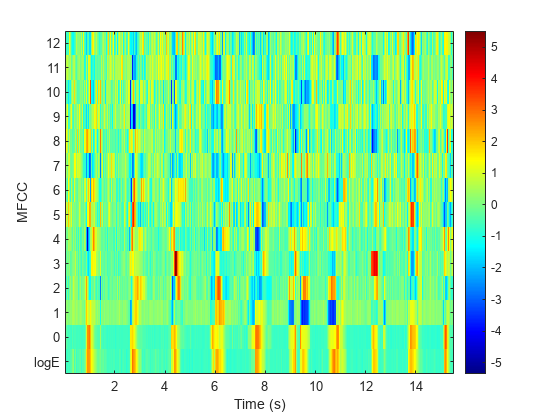

mfcc(audioIn,fs)

*Copyright 2021 The MathWorks, Inc.*